boat.L = 0.4;         % length in meters
boat.W = 0.2;         % width in meters
boat.HB = boat.W / 2;  % half breadth in meters
boat.D = 0.1;         % depth in meters

%boat.mass = 18;       % kg
boat.n = 2;         % shape parameter (dimensionless)
boat.density = 500; %kg/m^3

water_density = 1000; %kg/m^3
colormap;
clear mesh;

mesh.dy = 0.001;
mesh.dz = 0.001;
mesh.dx = 0.001;
mesh.ys = -boat.HB:mesh.dy:boat.HB;
mesh.zs = 0:mesh.dz:boat.D;
mesh.xs = -boat.L/2:mesh.dx:boat.L/2;
[mesh.xgrid, mesh.ygrid,mesh.zgrid] = meshgrid(mesh.xs, mesh.ys, mesh.zs);
[mesh.xgrid, mesh.ygrid] = meshgrid(mesh.xs, mesh.ys);

hull3D = computeHull3D(mesh,boat);
boat.num_cells = sum(hull3D(:));
boat.mass = boat.num_cells*boat.density*mesh.dx*mesh.dy*mesh.dz;
boat.mass_per_cell = boat.mass/boat.num_cells;
boiyant = boat.mass*9.81;

theta = 1;

masses3D = hull3D*boat.mass_per_cell;
boat.COM = centerOfMass3D(masses3D, mesh)

boat = struct with fields:
                L: 0.3000
                W: 0.2000
               HB: 0.1000
                D: 0.1000
                n: 2
          density: 500
        num_cells: 3022042
             mass: 1.5110
    mass_per_cell: 5.0000e-07
              COM: [4.7716e-18 -3.9800e-20 0.0640]


fun = @(d) massDiff3D(mesh, boat, theta, d);
d0 = boat.D/2;
d = fzero(fun, d0);
water = computeWater3D(d, theta, mesh);
sub_region = hull3D & water;
COB = centerOfMass3D(sub_region, mesh)

COB =     0.0000    0.0008    0.0431


force = [0, -boiyant*sind(theta), boiyant*cosd(theta)]

force =          0   -0.2587   14.8209


r = COB - boat.COM

r =     0.0000    0.0008   -0.0209


moment = cross(r, force)

moment =     0.0072   -0.0000   -0.0000


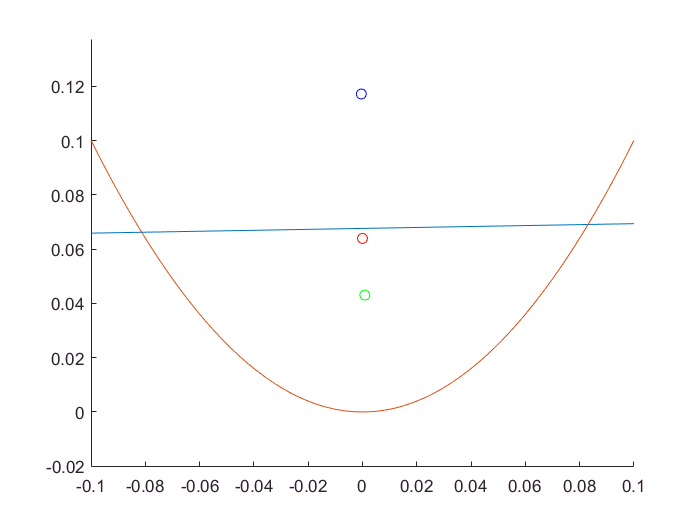

Y = -0.1:0.001:0.1;
station = (((2.*Y)./boat.W).^2).*boat.D;
waterline = tand(theta).*Y + d;
figure;
hold on;
plot(force(2)/(200) + COB(2), force(3)/(200) + COB(3), 'bo');
plot(COB(2), COB(3), 'go');
plot(boat.COM(2), boat.COM(3), 'ro');
plot(Y,waterline);
plot(Y,station);
xlim([-0.1,0.1]);
axis('equal');
hold off;

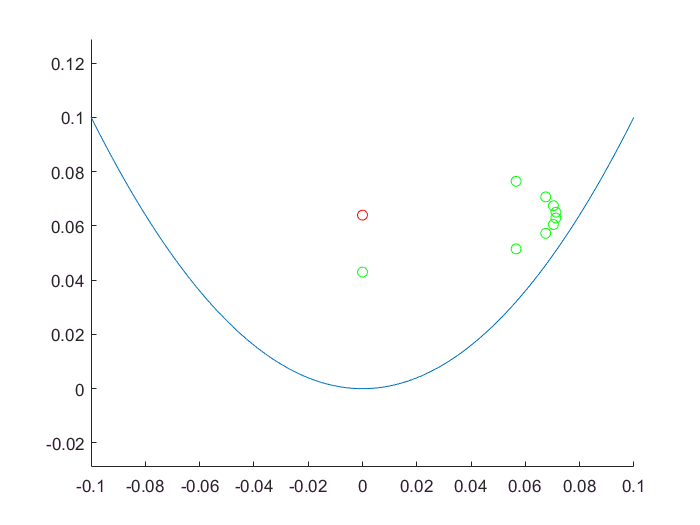


hull3D = computeHull3D(mesh,boat);
boat.num_cells = sum(hull3D(:));
boat.mass = boat.num_cells*boat.density*mesh.dx*mesh.dy*mesh.dz;
boat.mass_per_cell = boat.mass/boat.num_cells;

masses3D = hull3D*boat.mass_per_cell;

boat.COM = centerOfMass3D(masses3D, mesh);

figure;
hold on;
plot(Y,station);
torques = [];

plot(boat.COM(2), boat.COM(3), 'ro');
for theta = 0:20:160
    clear r
    fun = @(d) massDiff3D(mesh, boat, theta, d);
    d0 = boat.D/2;
    d = fzero(fun, d0);
    water = computeWater3D(d, theta, mesh);
    sub_region = hull3D & water;
    COB = centerOfMass3D(sub_region, mesh); %find COB
    plot(COB(2), COB(3), 'go');
    
    r = COB - boat.COM;
    boiyant = boat.mass*9.81;
    force = [0, -boiyant*sind(theta), boiyant*cosd(theta)];
    moment = cross(r,force);
    
   
   
    torques = [torques; moment];
  
end
axis('equal');
hold off;

% [X,Y,Z] = ndgrid(1:size(sub_region,1), 1:size(sub_region,2), 1:size(sub_region,3));
% pointsize = 30;
% scatter3(X(:), Y(:), Z(:), pointsize, sub_region(:));
% axis('equal');

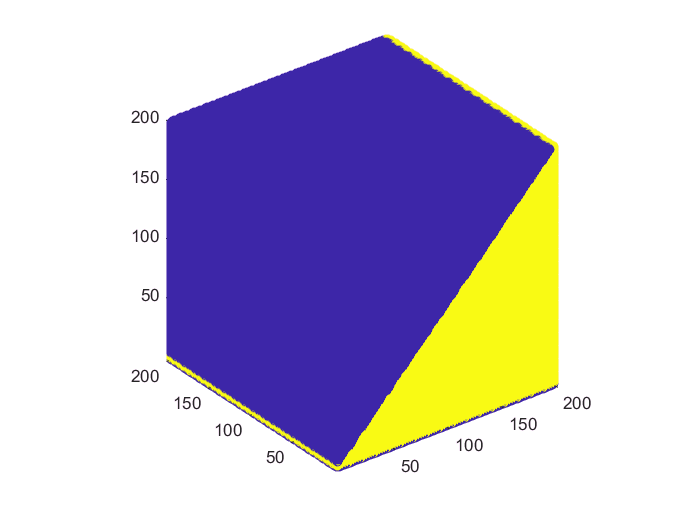

torques

figure;
thetas = 0:20:160;

torques =    -0.0000   -0.0000         0
    3.8691   -0.0000   -0.0000
    3.7491   -0.0000   -0.0000
    2.5454   -0.0000   -0.0000
    0.8950   -0.0000   -0.0000
   -0.8950    0.0000   -0.0000
   -2.5455    0.0000   -0.0000
   -3.7487    0.0000   -0.0000
   -3.8691    0.0000   -0.0000


plot(thetas,torques(:,1), 'bo');
torques(:,1)

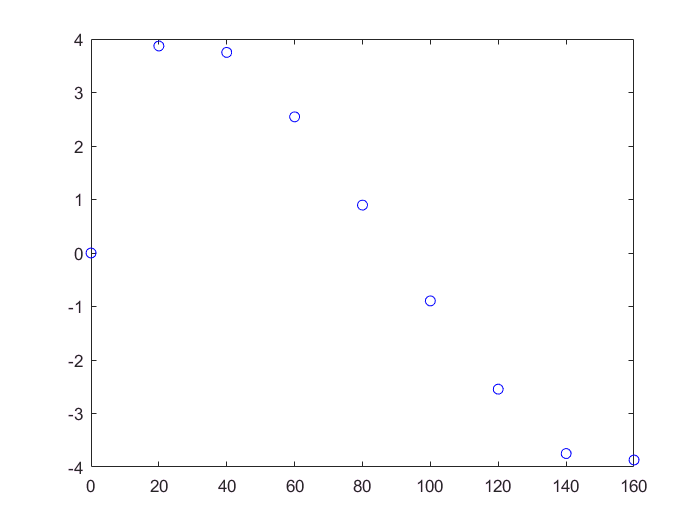

function COM = centerOfMass3D(masses, mesh)

    M = sum(masses(:));

ans =    -0.0000
    3.8691
    3.7491
    2.5454
    0.8950
   -0.8950
   -2.5455
   -3.7487
   -3.8691


    x_masses = masses.*mesh.xgrid;
    x_COM = sum(x_masses(:))/M;
    y_masses = masses.*mesh.ygrid;
    y_COM = sum(y_masses(:))/M;
    
    z_masses = masses.*mesh.zgrid;
    z_COM = sum(z_masses(:))/M;
    COM = [x_COM,y_COM, z_COM];
end




function water = computeWater3D(d,theta,mesh)
    % water: compute the level of the water
    % d: depth of waterline in meters
    % theta: angle of waterline in degrees
    % mesh: structure containing ys and zgrid
    % returns: logical matrix
    
    y = mesh.ygrid;
    
    z = tand(theta) .* y + d;
    if theta <= 90
        water = mesh.zgrid <z;
    end
    if theta > 90
        water = mesh.zgrid > z;
    end
end


function hull = computeHull3D(mesh, boat)
    %computes a 3D hull with breadth B, depth D, and 
    %length L
    B = boat.W;
    D = boat.D;
    L = boat.L;
    center_station = (((2.*mesh.ygrid)./B).^2).*D;
    profile = (((2.*mesh.xgrid)./L).^4).*D;
    z = center_station + profile;
    hull = mesh.zgrid  >z;
end



function diff = massDiff3D(mesh,boat,theta,d)
    
%     for a value of theta and d, finds the differnce 
%     in boiyant and weight forces
    
    hull3D = computeHull3D(mesh, boat);
    boat.num_cells = sum(hull3D(:));
    boat.mass = boat.num_cells*mesh.dy*mesh.dz*mesh.dx*boat.density;
    water = computeWater3D(d, theta, mesh);
    sub_region = hull3D & water;
    
    displaced_water = sum(sub_region(:))*mesh.dx*mesh.dy*mesh.dz*1000;
    
    diff = boat.mass - displaced_water;
end

function hull = squareHull(mesh, boat)
    %computes a 3D hull with breadth B, depth D, and 
    %length L
    z = 0;
    hull = mesh.zgrid  >= z;
end

